# Compress Deep Learning Models, Generate Code, and Profile Performance

This exercise requires **Deep Learning Toolbox Model Quantization Library, MATLAB Coder Interface for Deep Learning, **and a** GNU C++ Compiler, such as **`g++`**.** Check `mex -setup C++.`

Exercise 3 covers a three-part workflow to optimize deep learning models for deployment. Initially, you will apply the projection technique to **compress** a deep learning model, reducing its size while aiming to retain its accuracy. Following the compression, you will use Simulink to **generate C code** for both the original and compressed models. The final part involves **performance profiling**, where you will compare the execution time of the generated code for both models, providing insights into the efficiency improvements achieved through model compression. This exercise is designed to equip you with practical skills in model optimization, code generation, and performance analysis, essential for deploying efficient deep learning models in real-world applications.

## Load Previously Trained LSTM Network

clear
origFileName = 'DLmodel_ref_stackedLSTM.mat';
projectedFileName = 'DLmodel_ref_stackedLSTM_Projected.mat';
load(origFileName);
recurrentNet.Layers
analyzeNetwork(recurrentNet)

Note that the original LSTM network has 463.4k learnables. By default, in MATLAB, DL network learnables are stored in single-precision, floating-point format (fp32). At 4 bytes (32 bits) per learnable, this translates to a total learnables size of **~1.85 MB**. 

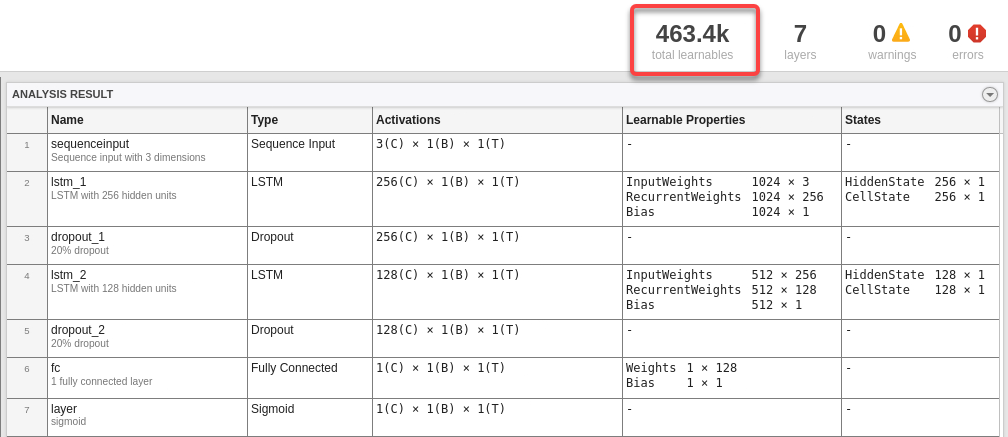

## Data Preparation

dataFolder = helper.getDataFolder;
chunkSize = 500;
numFeatures = 3;

trainingFile = fullfile(dataFolder,"Train","TRAIN_LGHG2@n10degC_to_25degC_Norm_5Inputs.mat");
[XTrain,YTrain] = helper.setupDataLSTM(trainingFile,chunkSize,numFeatures);
validationFile = fullfile(dataFolder,"Validation", "01_TEST_LGHG2@n10degC_Norm_(05_Inputs).mat");
[XVal,YVal] = helper.setupDataLSTM(validationFile,chunkSize,numFeatures);

for i = 1:numel(XTrain)
    XTrain{i} = XTrain{i}.';
    YTrain{i} = YTrain{i}.';
end
for i = 1:numel(XVal)
    XVal{i} = XVal{i}.';
    YVal{i} = YVal{i}.';
end

## Model Compression - Projection

### Understanding network compression with projection

To compress a neural network, MATLAB uses a technique that involves projecting the network's layers into smaller parameter subspaces, thereby reducing the memory footprint of the model. This is done by introducing projector matrices that transform the learnable parameters into a lower-dimensional space without significantly compromising prediction accuracy. A projected deep neural network can also exhibit faster forward passes (inference) or deployed to embedded hardware using library-free C or C++ code generation, making projection a powerful technique for both reducing memory requirements and boosting throughput. To learn more about the algorithm based on principal component analysis (PCA) underlying network projection, refer to [this page](https://www.mathworks.com/company/newsletters/articles/compressing-neural-networks-using-network-projection.html).

As of R2024a, the following network layers support compression with projection:

- `convolution2dLayer`

- `fullyConnectedLayer`

- `lstmLayer`

- `gruLayer`

### Explore Compression Levels

A trade-off exists between the amount of compression we apply to the network and its accuracy. In general, reducing the number of learnable parameters in a pretrained network will reduce its accuracy. Let's experiment by compressing the network with projection by a range of increasing amounts. To do this, let's iterate over 20 values of the `ExplainedVarianceGoal` in put argument to the `compressNetworkUsingProjection `function and plot the results. Then, we can decide on a worthwhile trade-off point between network size and accuracy.

The explained variance of a network details how well the space of network activations can capture the underlying features of the data. To explore different amounts of compression, you can iterate over different values of the ExplainedVarianceGoal option of the compressNetworkUsingProjection function and compare the results.

mbSize = 48;
mbq = minibatchqueue(...
    arrayDatastore(XTrain(1:10:end-1),OutputType="same",ReadSize=mbSize),...
    MiniBatchSize=mbSize,...
    MiniBatchFormat="TCB",...
    MiniBatchFcn=@(X) cat(3,X{:}));

npca = neuronPCA(recurrentNet, mbq); % Create Neuron Principal Component Analysis (PCA) object
numValues = 20;
explainedVarGoal = 1 - logspace(-3,0,numValues);
explainedVariance = zeros(1,numValues);
learnablesReduction = zeros(1,numValues);
accuracy = zeros(1,numValues);

S = load(validationFile);
XTest = S.X(1:numFeatures,:);
YTest = S.Y';

for i = 1:numel(explainedVarGoal)
    varianceGoal = explainedVarGoal(i);

    [dlnetProjected,info] = compressNetworkUsingProjection(recurrentNet, npca, ...
        ExplainedVarianceGoal=varianceGoal, ...
        VerbosityLevel="off");

    explainedVariance(i) = info.ExplainedVariance;
    learnablesReduction(i) = info.LearnablesReduction;
    
    YPredProjected = predict(dlnetProjected, dlarray(XTest,"CTB"));
    YPredProjected = extractdata(YPredProjected(:));
    accuracy(i) = sqrt(mean((YTest - YPredProjected).^2));
end

Visualize the effect of the different settings of the explained variance goal.

figure
tiledlayout("flow")
nexttile
plot(learnablesReduction,accuracy,'+-')
hold on
plot(0.93, 0.128, 'r*')
xlabel("Learnables Reduction")
ylabel("RMSE")
title("Effect of Explained Variance Goal")

nexttile
plot(learnablesReduction,explainedVariance,'+-')
ylim([0 inf])
ylabel("Explained Variance")
xlabel("Learnables Reduction")

The graph shows that an increase in learnable reduction has a corresponding increase in RMSE (decreace in accuracy). A learnable reduction value of around **93%** shows a good compromise between explained variance and RMSE.

### Compress stacked-LSTM via Projection of Layers

dlnetProjected = compressNetworkUsingProjection(recurrentNet, mbq, LearnablesReductionGoal = 0.93); % project network with 93% learnables reduction value
analyzeNetwork(dlnetProjected)

The new, projected network has 32.3k learnables. Still stored in `fp32`, the size now amounts to **~0.13 MB**. 

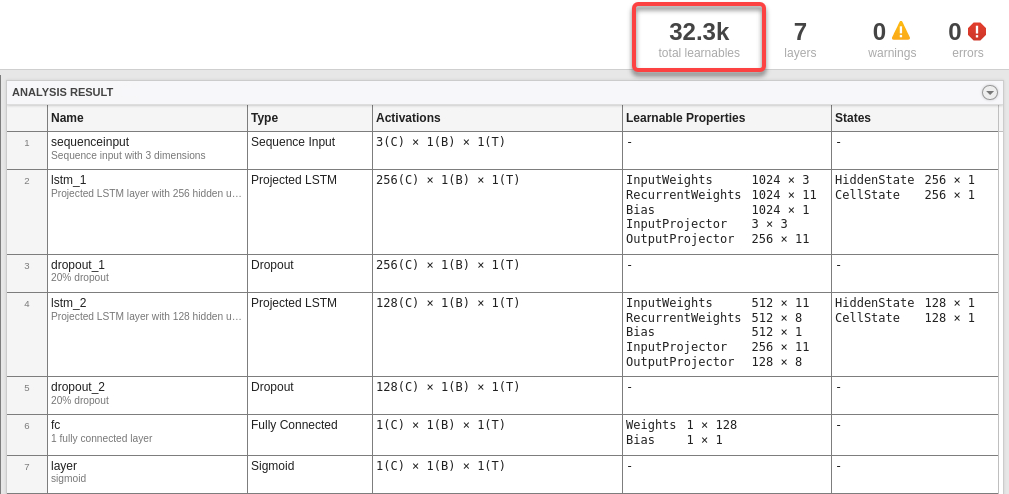

### Fine-tune Compressed Stacked-LSTM Network

Starting with a pretrained network, the projected network equivalent can be directly computed as demonstrated above. Although a high degree of data covariance is retained, the network may need fine-tuning as accuracy can drop following the compression. This could be a result of higher order nonlinear relations between neurons in the network needing to readjust given the linear transformation or a compounding effect if many layers are projected at once. The projected model provides a good initialization for fine-tuning by further retraining. The fine-tune retraining typically takes far fewer epochs for the accuracy to plateau and can largely recover, in many cases, the accuracy of the original network.

doTraining = false; % Set to true if you would like to run fine-tuning, otherwise, the script will load a fine-tuned model from file below

if doTraining  

    options = trainingOptions("adam", ...
        MaxEpochs = 300,...
        ExecutionEnvironment = "auto", ...
        InitialLearnRate = 1e-2, ...
        LearnRateSchedule = "piecewise",...
        LearnRateDropPeriod = 120,...
        LearnRateDropFactor = 0.1,...
        GradientThreshold = 1,...
        Shuffle = "every-epoch",...
        Verbose = false,...
        ValidationFrequency = 10, ...
        MiniBatchSize = 64, ...
        Plots = "training-progress", ...
        ValidationData = {XVal,YVal});
    
    recurrentNetProjected = trainnet(XTrain,YTrain,dlnetProjected,"mse",options);
else
    load(projectedFileName);
end

testFile = fullfile(dataFolder,"Test","01_TEST_LGHG2@n10degC_Norm_(05_Inputs).mat");
S = load(testFile);

XTest = S.X(1:numFeatures,:)';
YTest = S.Y;

YPredProjected = predict(recurrentNetProjected, XTest);

[RMSEProjectedNN,residualsProjectedNN] = rmse(YTest,YPredProjected);

figure
plot(residualsProjectedNN);
title("Residuals","RMSE: " + RMSEProjectedNN)
xlabel("Sample")
ylabel("Y-Y_{pred}")
% Calculate network accuracy
1 - RMSEProjectedNN

## Generate Code from Deep Learning Models

Open the model:

open_system("SOC_model_Code_Gen");

To generate code from the **AI subsystem** and inspect the **Static Code Metrics** Report:

- Right-click the **AI Subsystem**

- Select **C/C++ Code** > **Build This Subsystem**.

Optional: here are the configuration steps that have been set up for you for your reference. These configurations have been saved with the model.

- Click into the **AI** **subsystem** and apply the same settings for both LSTM and LSTM Projected subsystems. On the **Subsystem Block** pane, under **Component**, click **Atomic Subsystem**. Right-click the subsystem, and select **Block Parameters** **(subsystem)**. In the **Code Generation** tab, set **Function Packaging** to **Nonreusable function**.

- Open the Configuration Parameters dialog box. In the Simulink Editor, on the **Modeling** tab, click **Model Settings**.

- On the **Code Generation** pane, under **Target selection**, specify the system target file as `ert.tlc`.

- Under **Build process**, uncheck **Generate code only**

- On the **Code Generation **> **Optimization** pane, set **Leverage target hardware instruction set extensions **to **None**

## Inspect Generated Code

Click "Open Report" on the "C Code" tab on the Simulink Toolstrip.

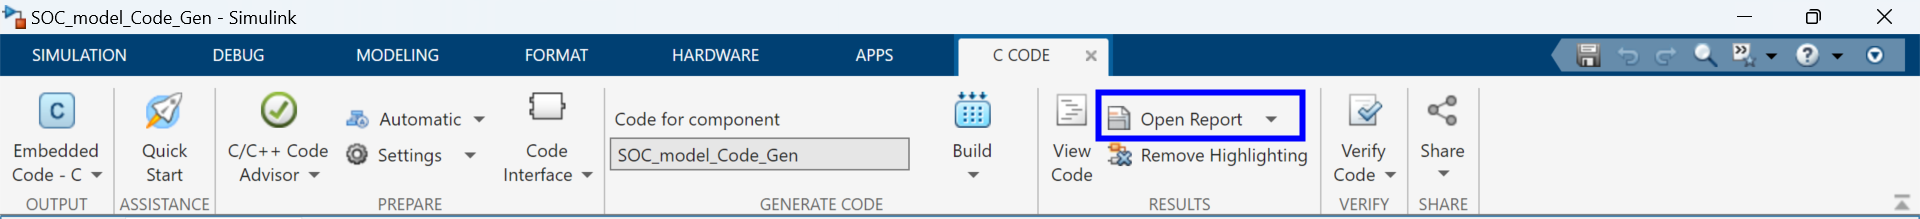

After the **Code Generation Report** window opens, in the "Code" section on the left-hand side panel, click through the "Model files" to inspect the content of the code.

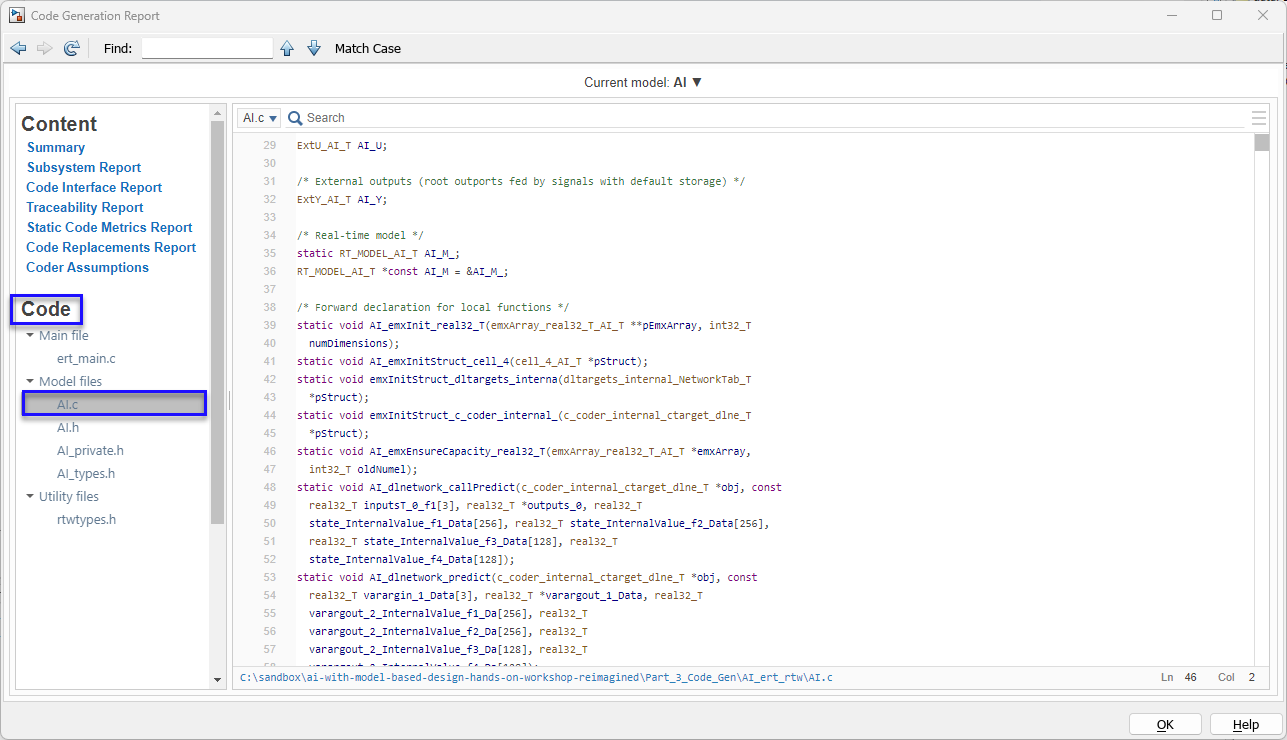

## Measure Code Execution Time

Run the model in SIL mode and collect profiling information. On the **Apps** tab, in the **Code Verification, Validation, and Test** group, open the **SIL/PIL Manager** app.

On the **SIL/PIL** tab, ensure that the mode is set to "SIL/PIL Only". Make sure **SIL/PIL Mode** option under the **Prepare** section is set to `Software-in-the-loop (SIL)`.

Set Stop Time to **100** to speed up the profiling process while running inference on a reasonbly large input data set**. **On the **SIL/PIL** tab, click **Run SIL/PIL** to run the simulation and log profiling metrics.

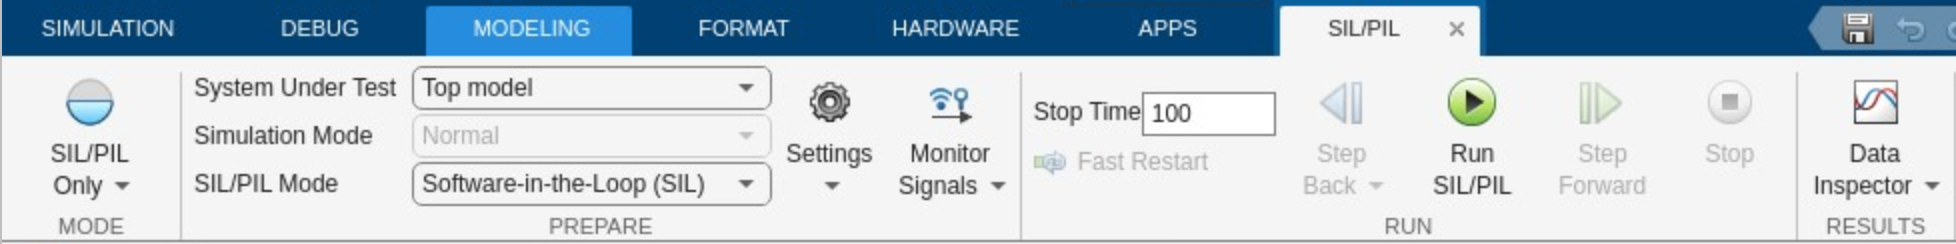

After the SIL verification is complete, in the **Results** section of the **SIL/PIL** tab, click the triangle to expand on the list options. Select **Code Profile Analyzer** in the dropdown list.

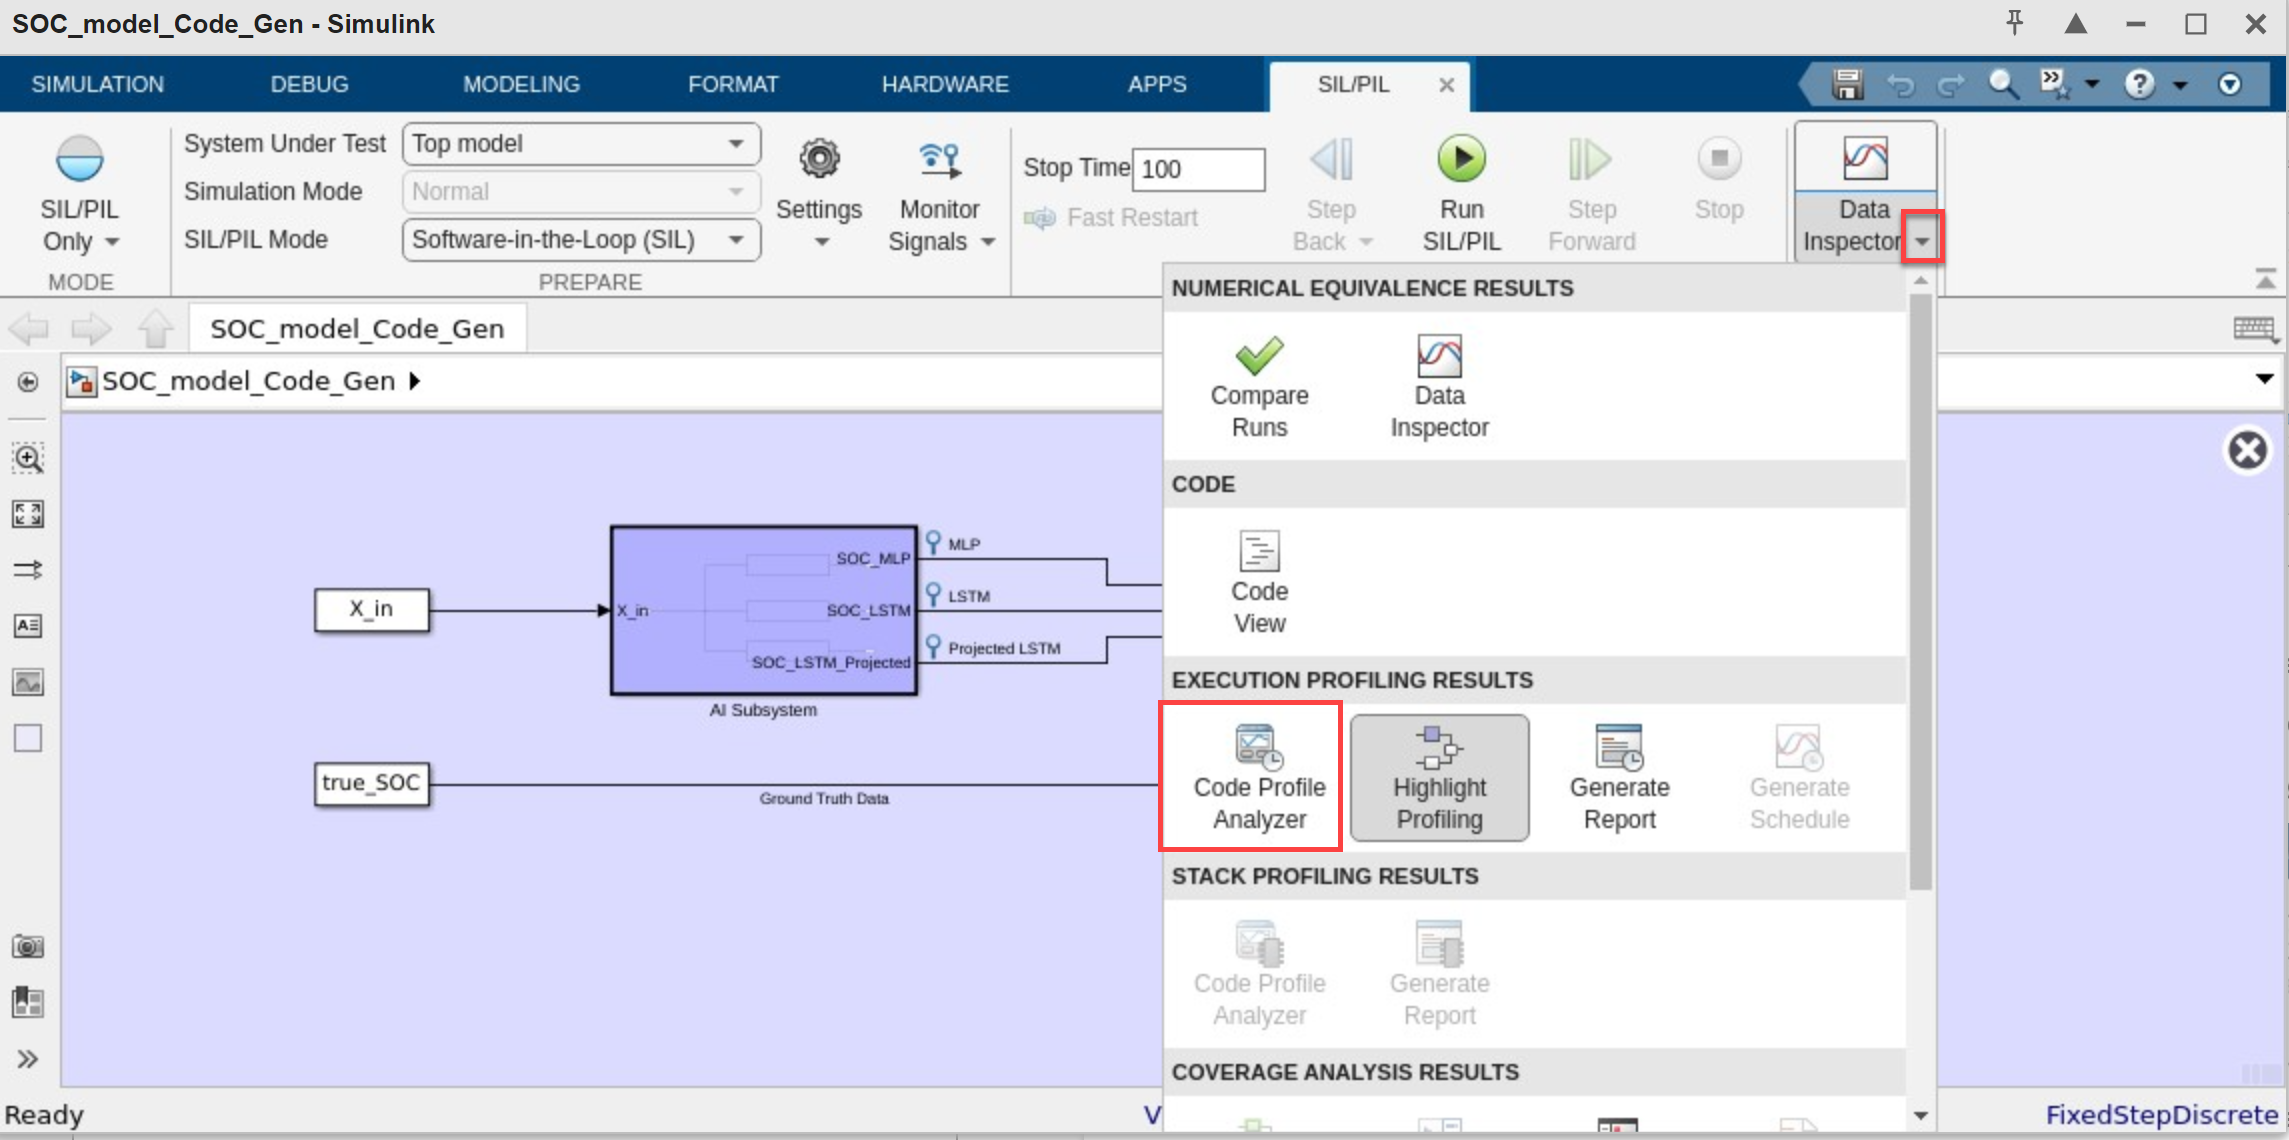

In the **Code Profile Analyzer **window, under the **Analysis** section, select **Function Execution.**

Change **Time unit** to **Microseconds (us) **and observe the **Average Execution Time** of different subsystems (MLP, LSTM, Projected LSTM).

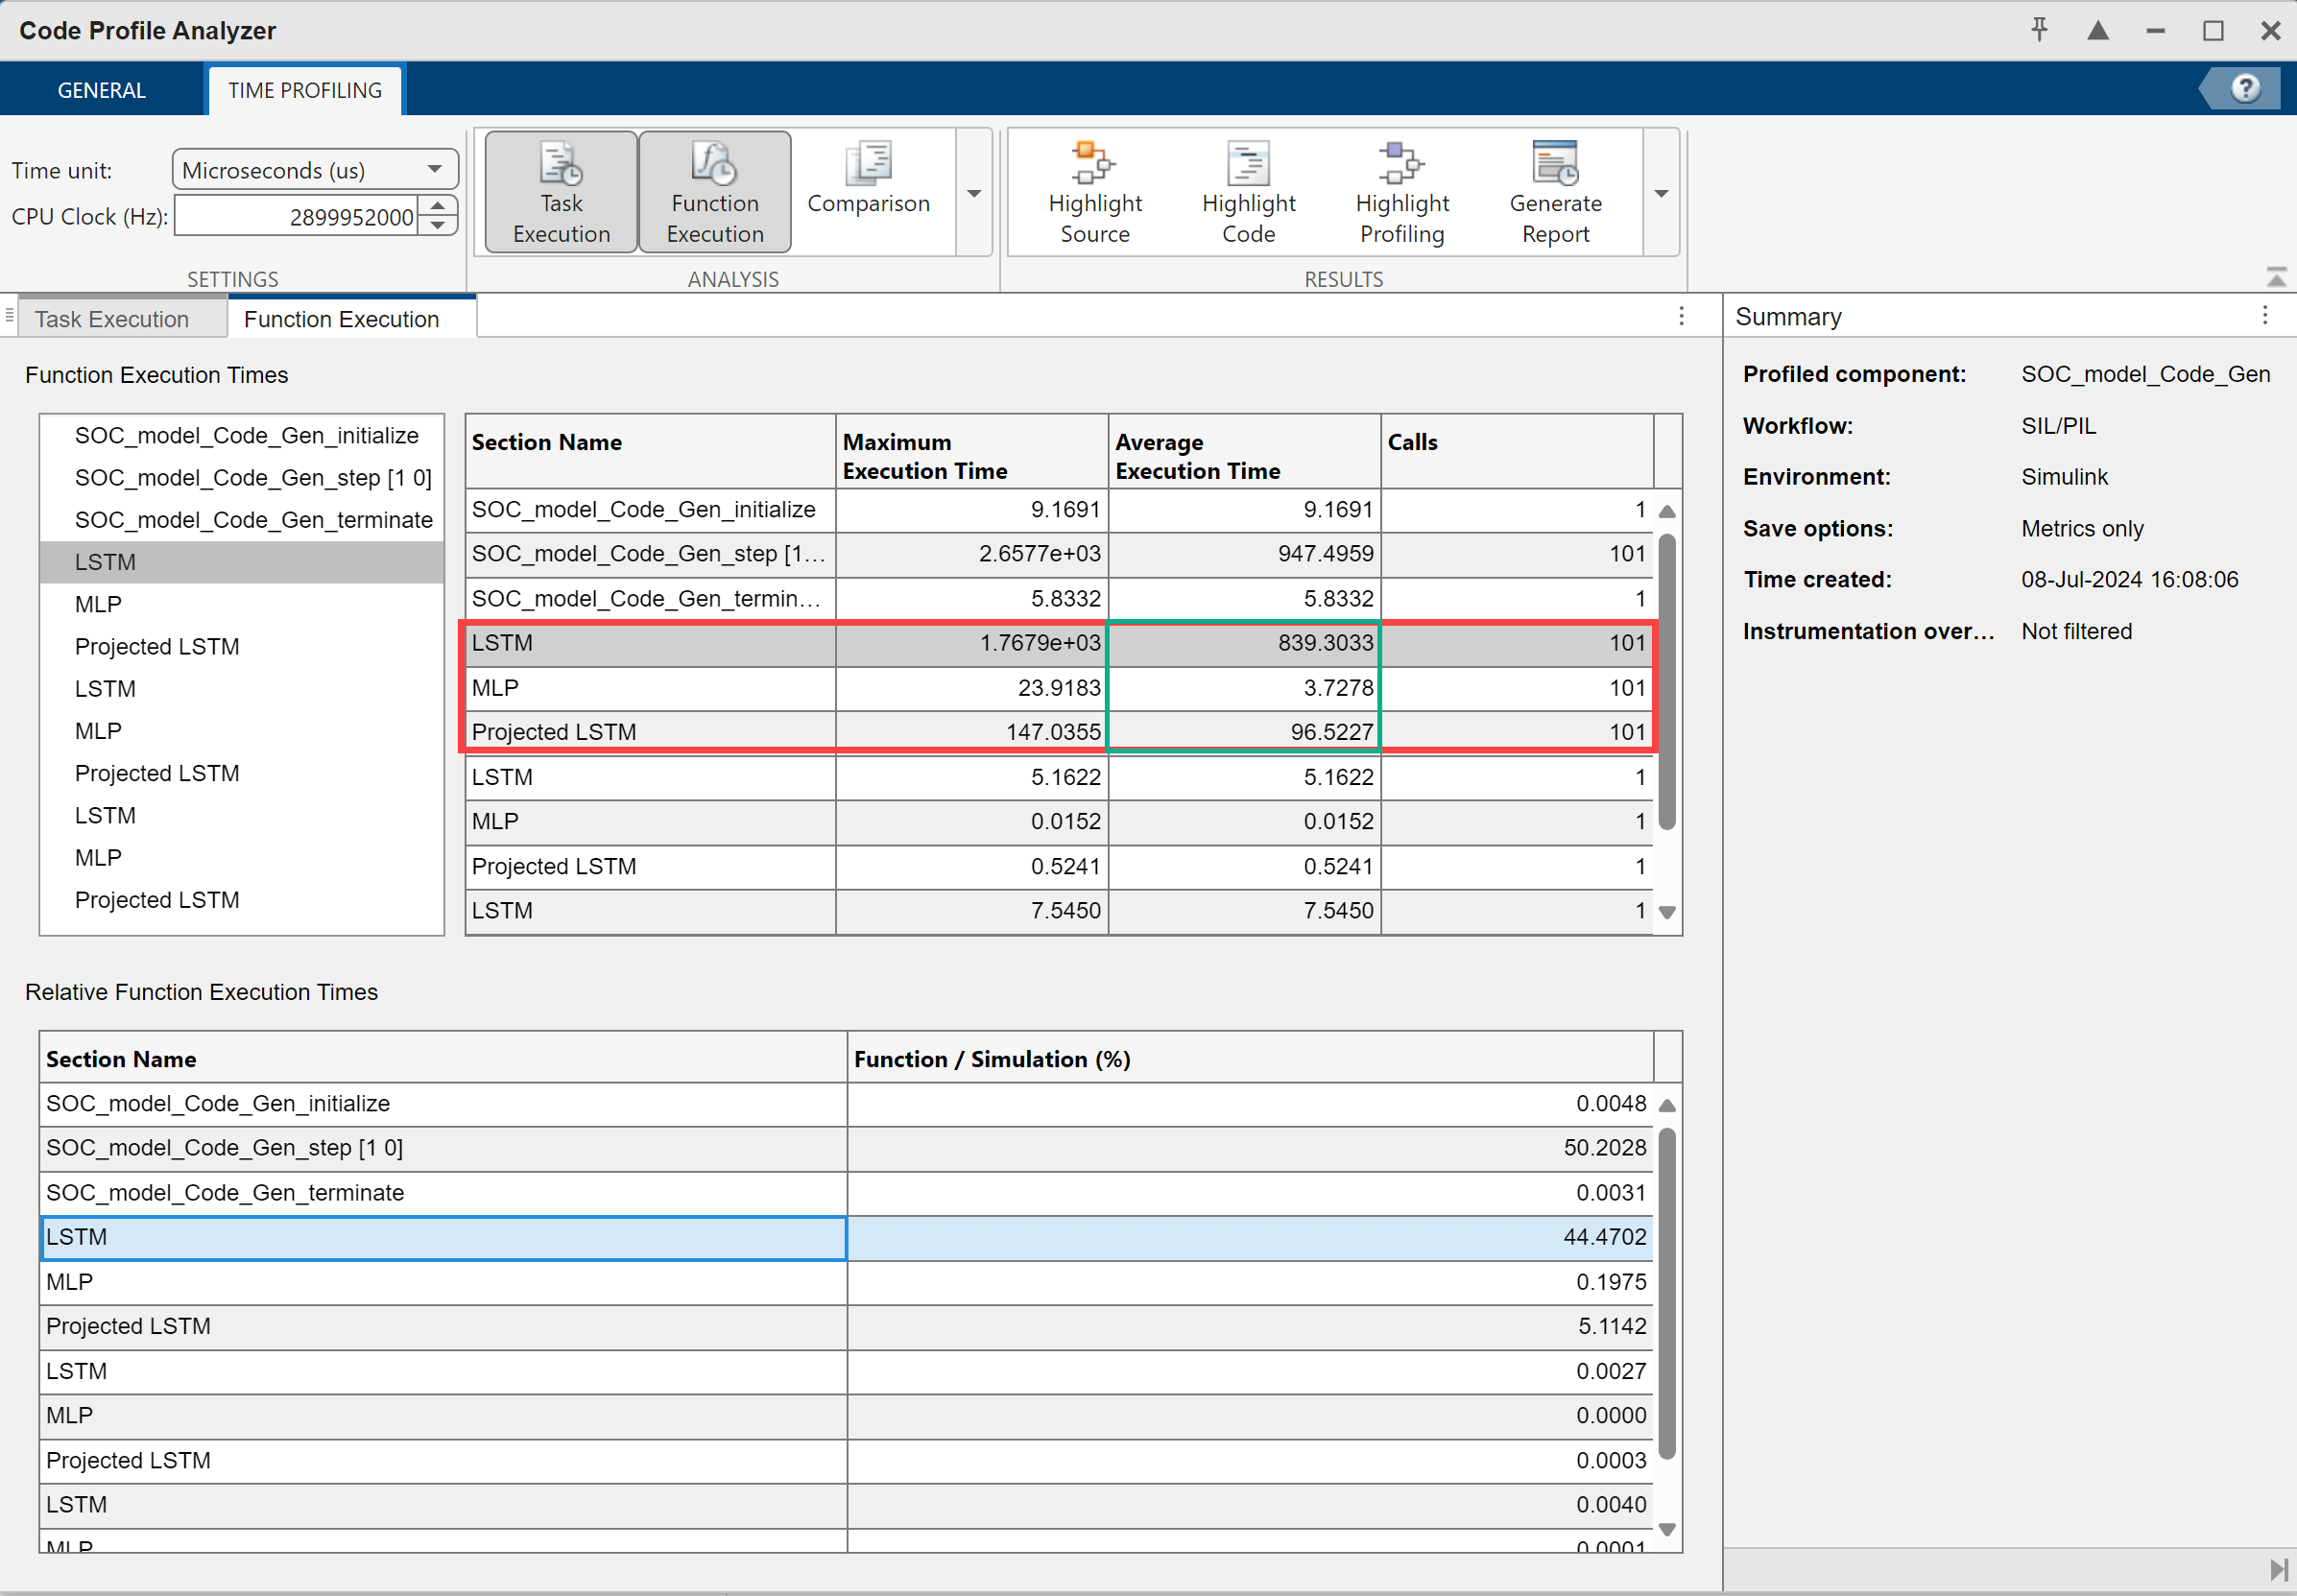

Notes on interpreting the results:

You might see functions of the same name showing up multiple times in the "Section" column. In this example, "MLP", "LSTM", and "Projected LSTM" appear three times. This is because there are three separate functions being called on a single component:

- **Initialize** - called exactly once for initializing the simulation

- **Step** - called at each time step as simulation continues to run

- **Terminate** - called exactly once for terminating the simulation

**Code Profile Analyzer** shows the execution times of all three functions of a component. **Initialize** and **Terminate** functions have small execution costs, whereas the execution time for **Step** function is much more significant - this is what we focus on for the analysis, as indicated in the blue box.

Optional: here are the configuration steps that have been set up for you for your reference. These configurations have been saved with the model.

To configure code execution profiling for SIL mode simulation:

- Open the **Configuration Parameters** dialog box. In the Simulink Editor, on the **Modeling** tab, click **Model Settings**.

- In the **Code Generation** > **Verification** pane, under **Code execution time profiling**, select the **Measure task execution time** check box.

- For the function execution times, select `Coarse (referenced models and subsystems only)` from the **Measure function execution times** list. This option allows you to analyze generated function code for the main model components.

- In the **Workspace variable** field, specify the variable name as `executionProfile`. When you run the simulation, the software generates a variable with this name in the MATLAB base workspace. The variable, an object of type `coder.profile.ExecutionTime`, contains the execution time measurements. In the **Data Import/Export** pane, under **Save to workspace or file**, select the **Single simulation output** check box and specify the variable name as `out`. The software also creates the `executionProfile` variable in the `out` variable (`Simulink.SimulationOutput` object).

- In the **Code Generation** > **Verification** pane, under **Code execution time profiling**, select `Metrics only` from the [Save options](https://www.mathworks.com/help/ecoder/ref/saveoptions.html) (Embedded Coder) list. This option helps reduce bandwidth usage for the communication channel between Simulink and the target application.

- In the **Hardware Implementation** pane, select the type of hardware to use to implement the system represented by the model. This example uses the default value `x86–64 (Linux64)`.

- Click **OK**.

The prediction implementations that use MATLAB Function blocks require support for variable signals to be enabled for code generation. To enable code generation support:

- Open the Configuration Parameters dialog box. In the Simulink Editor, on the **Modeling** tab, click **Model Settings**.

- In the **Code Generation** > **Interface** pane, under **Software environment**, select the **variable-size signals** check box.

Root mean squared error helper function

function [rmseValue,residuals] = rmse(y,t)
    residuals = y(:)-t(:);
    rmseValue = sqrt(mean(residuals.^2));
end

*Copyright 2024 The MathWorks, Inc.*